Linear Sensory Recalibration Model of Implicit Adaptation. 

Mengzhan Liufu, Jingyue Xu, Xueqian Deng, Chen Yang, Zhiguo Huang. Jan. 14 2022. 

Adapted from Hadjiosif, A. M., Krakauer, J. W., & Haith, A. M. (2021). Did We Get Sensorimotor Adaptation Wrong? Implicit Adaptation as Direct Policy Updating Rather than Forward-Model-Based Learning. *The Journal of Neuroscience*, *41*(12), 2747–2761. [https://doi.org/10.1523/JNEUROSCI.2125-20.2021](https://doi.org/10.1523/JNEUROSCI.2125-20.2021)

To see how simulated mirror-reversal adaptation varies with the width (σ) and learning rate (η) of the basis functions, and the saturation limit (A), select these parameters and click "Simulate". 

# Simulate Sensory Recalibration Model of Implicit Adaptation. 

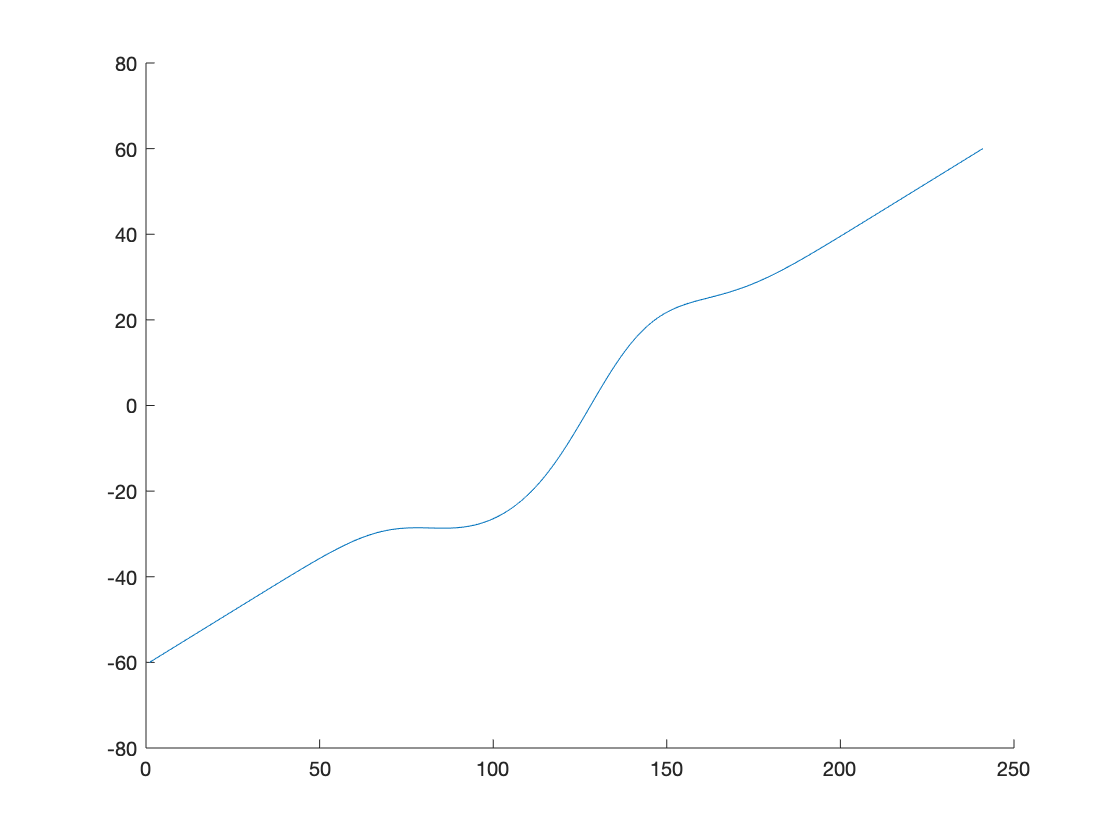

%Specify width of basis function
sigma =6;
eta =0.0001;
sat_limit =18;
seed_rng =48;
 

sigma_noise = 2;

rng (seed_rng); % fix randomization so simulations are reproducible

% initiate basis functions
delta_c = 0.05;
c = -60:delta_c:60;
priop = -60:.5:60; 
w = zeros(size(c));
% proprio is the kernel of proprioception

% Learning (note that Ntrials is more than needed to simulate Experiment 2,
% which is 24 cycles (168 trials, i.e. 7 targets x 24 trials; and steady-state
% analysis uses cycles 13:24)
Ntrials = 120;

[u_out,y_out,te] = deal(NaN(1,Ntrials));

% Load targets used in experiments
vision = cell2mat(struct2cell(load("targetdata210trials.mat")));
vision = vision(1:120);
possibleivusalgoals = [-12;-9;-6;-3;0;3;6;9;12;15];
w_sat_limit = sat_limit*delta_c/sigma/sqrt(2*pi);

%basis functions
B = NaN(length(c),length(priop));
for i=1:length(c)
    B(i,:) =  exp(-(priop-c(i)).^2/(2*sigma^2));
end

priop_map = NaN(Ntrials,length(priop));
absoluteerror = [0 0];

for i=1:Ntrials
    priop_map(i,:) = priop + sigmoid_saturation(w,w_sat_limit)*B;
    % current map
    
    [~,i_t] = min((priop-vision(i)).^2);
    %supposedly output
    
    priopout(i) = priop_map(i,i_t) + sigma_noise*randn;
    %add randomness
    
    % apply perturbation
    onlinecursor(i) = - priopout(i); % mirroring
    [~,i_thokin] = min((priop-onlinecursor(i)).^2);
    prioprime(i) = priop_map(i,i_thokin) + sigma_noise*randn;
    
    [~,i_selected] = min(abs(priop-vision(i)));
    
    %priop error
    prioperror(i) = -(prioprime(i) - priopout(i));
    
    % Absolute Error
    absoluteerror(i) = onlinecursor(i) - priopout(i);
    
    % learning update
    w = w + eta*prioperror(i)*B(:,i_selected)';
end

lins = lines;

figure; hold on;
plot(priop_map(90,:));

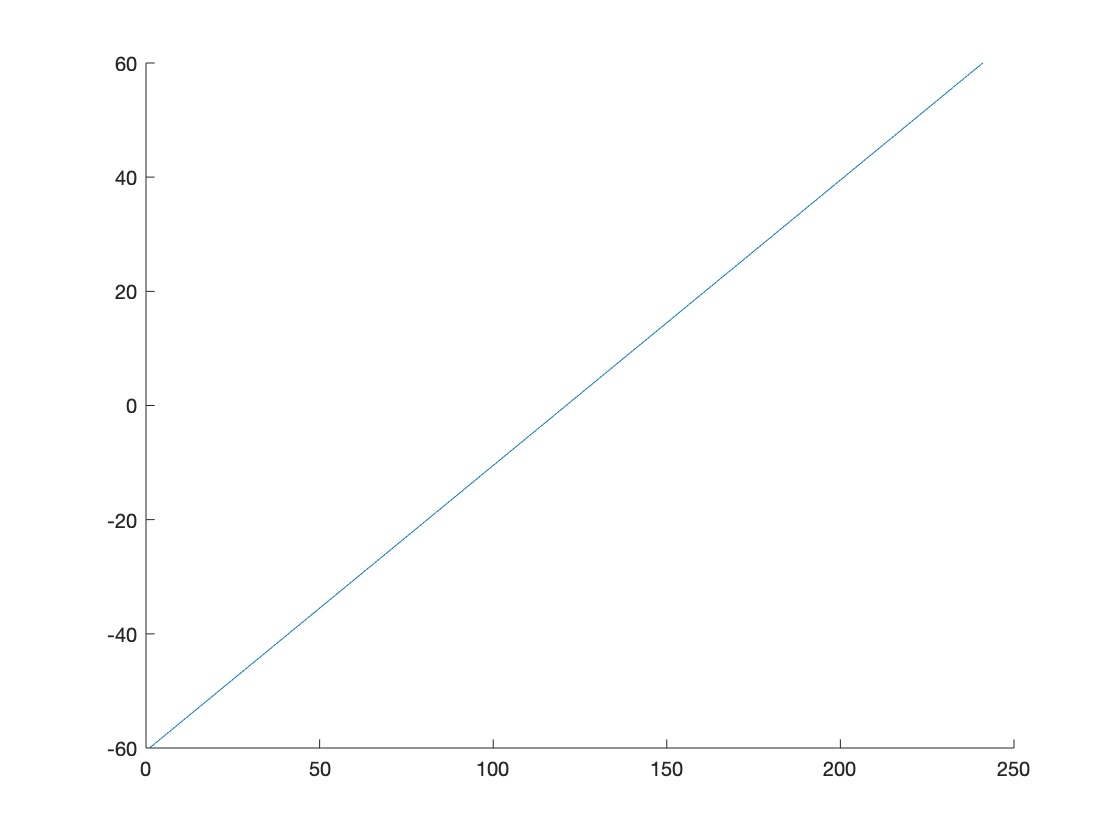


figure; hold on;


plot(priop);

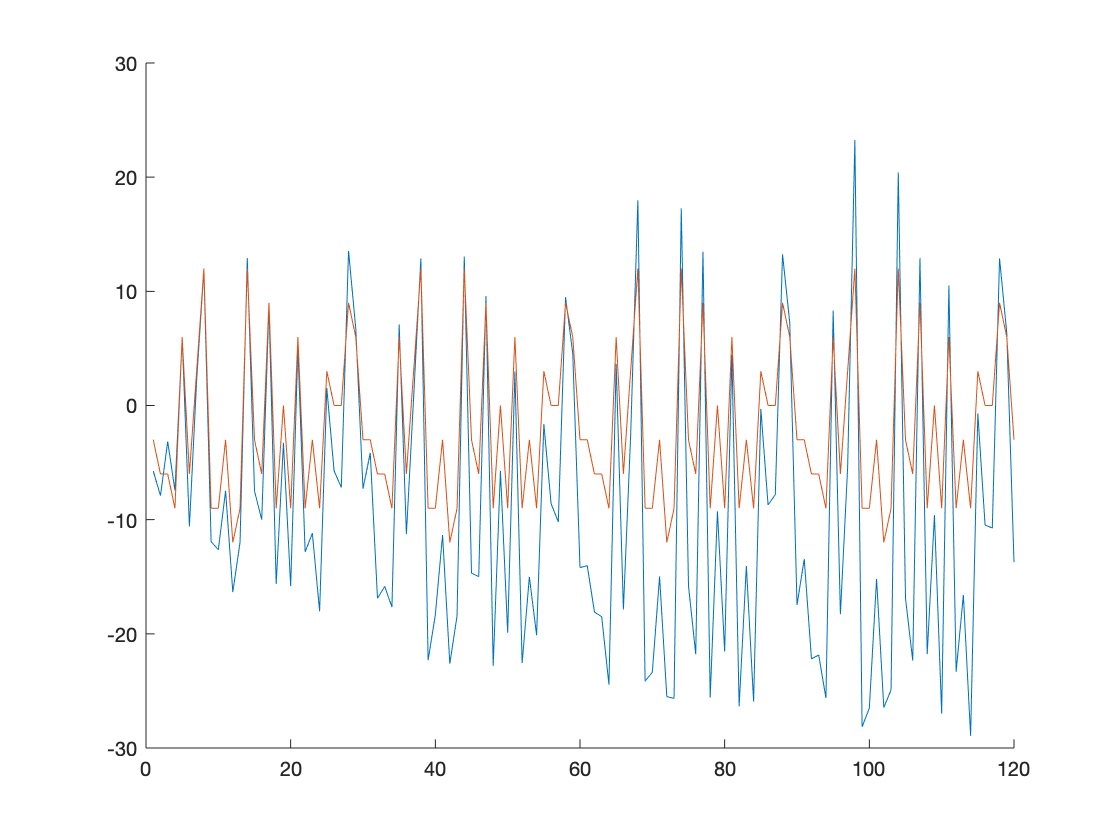

figure;hold on;
plot(priopout);
plot(vision);

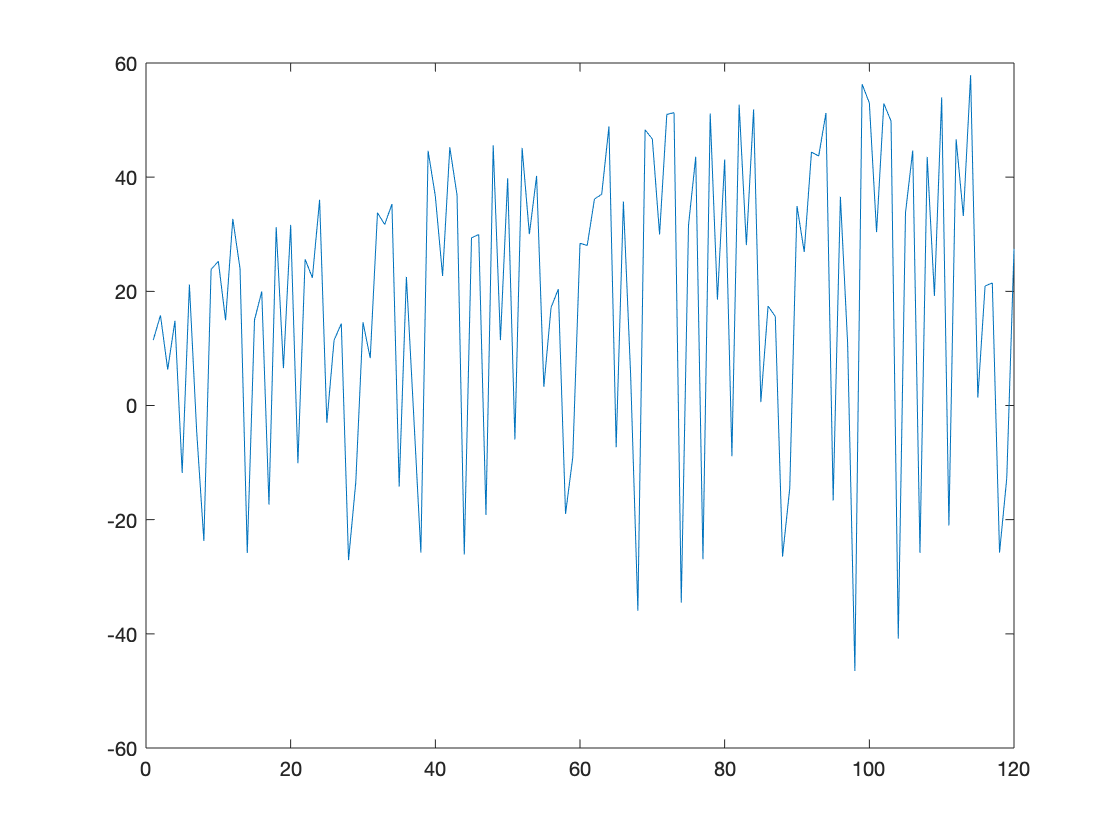


figure;
plot(absoluteerror);

function y = sigmoid_saturation(x,sat_limit)

y = sat_limit*erf(sqrt(pi)/2*x/sat_limit); end